img1 = im2double(imread('../FTIR.bmp'));
img2 = im2double(imread('../phone.bmp'));
img3 = im2double(imread('../latent.bmp'));

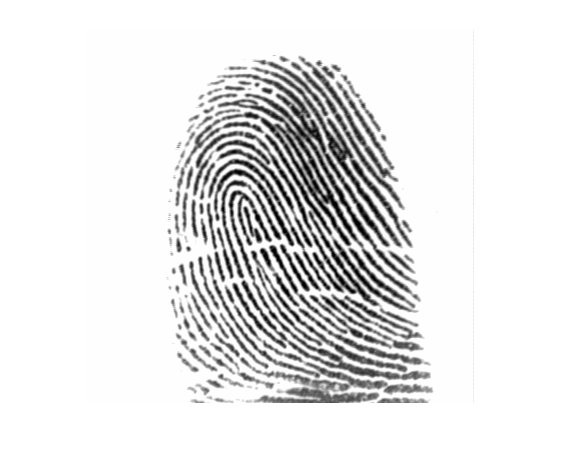

img = img1;
[loimg1, lfimg1, lmimg1, filtered] = localdft2(img);
imshow(img);

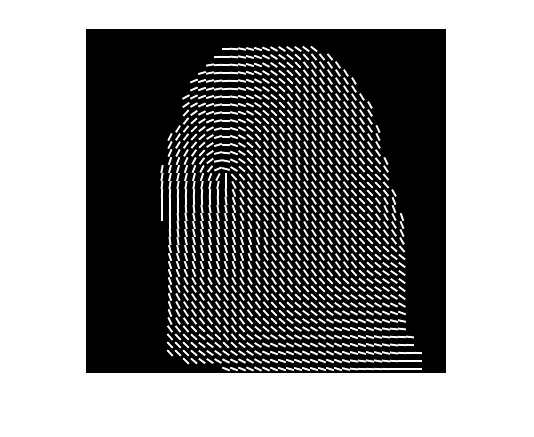

imshow(loimg1);

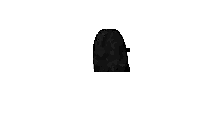

imshow(lfimg1, []);

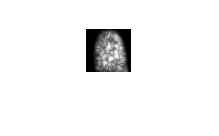

imshow(lmimg1, []);

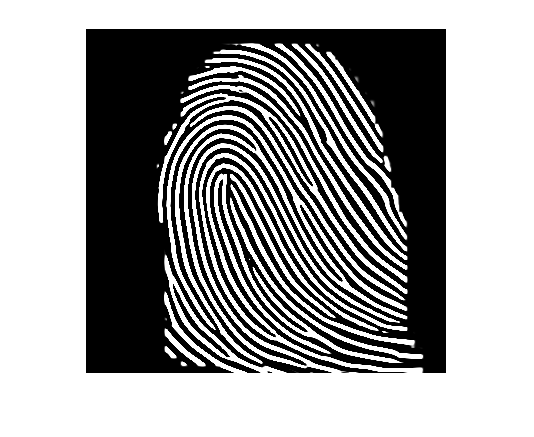

imshow(filtered);

function [local_orient, local_freq, local_mag, filtered] = localdft2(img)
    [width, height] = size(img);
    M = floor(width/8) - 3;
    N = floor(height/8) - 3;
    angs = zeros(M, N);
    local_freq = zeros(M, N);
    local_mag = zeros(M, N);
    local_orient = zeros(M*8, N*8);
    filtered = zeros(M*8, N*8);
    
    for i = 1 : M
        for j = 1 : N   
            dft = fftshift(fft2(img(8*i-7:8*i+24, 8*j-7:8*j+24), 32, 32));
            dft = abs(dft);
            [maxi, maxj] = maxpoint(dft);
            local_freq (i, j) = sqrt((maxi - 17)^2 + (maxj - 17)^2);
            local_mag (i, j) = abs(dft(maxi, maxj));
            
            if maxi ~= 17 || maxj ~= 17
                ang = atan((maxj-17)/(maxi-17));
                angs(i, j) = complex(cos(2 * ang), sin(2 * ang));
            end

        end
    end
    mask = zeros(size(local_freq));
    mask(local_mag > mean2(local_mag) * 0.85 - 0.2 * std2(local_mag) - 4 ...
        & local_freq < 8 & local_freq > 25 - 8.7 * mean2(local_freq)) = 1;
    
    se=strel('disk', 3);
    mask=imopen(mask, se);
    se=strel('disk', 15);
    mask=imclose(mask, se);
    
    angs = lpf(angs);
    img = histeq(img);
    for i = 1 : M
        for j = 1 : N
            if mask(i, j)
                line = zeros(8, 8);
                line(4:5, :) = 1;
                ang = 0.5 * angle(angs(i, j)) * 180 / pi;
                line = imrotate(line, ang, 'bicubic', 'crop');
                local_orient (8*i-7:8*i, 8*j-7:8*j) = line;
                
                ang = ang - 90;
                if ang < 0
                    ang = ang + 360;
                end
                [mag, phase] = imgaborfilt(img(8*i-7:8*i+24, 8*j-7:8*j+24), ...
                max(2 * local_freq(i, j), 7), ang);
                I = mag(13:20, 13:20) .* cos(phase(13:20, 13:20));
                filtered(8*i-7:8*i, 8*j-7:8*j) = I;
            end
        end
    end
    filtered = lpf(filtered);
    
end

function [maxi, maxj] = maxpoint(F)
    F(16:18, 16:18) = 0;
    [maxi, maxj] = find(F == max(F(:)));
    maxi = maxi(1);
    maxj = maxj(1);
end

function result = lpf(img) 
    h = fspecial('gaussian', 5, 1);
    result = imfilter(img, h,'replicate');
end